# kNN and Random Forests for non-linear regression

clear;
clc;
close all;
warning off all;

Archivo data

archivo_csv = 'comptagesvelo2015.csv';
datos = readtable(archivo_csv);
datos = removevars(datos, {'Date', 'Var2', 'Maisonneuve_1', 'ParcU_ZeltTest', 'Pont_Jacques_Cartier', 'Saint_LaurentU_ZeltTest'}); % eliminación de datos no necesarios

datos = normalize(datos, 'range');
disp(datos(1:10,:));

     Berri1        Boyer        Br_beuf      CSC_C_teSainte_Catherine_    Maisonneuve_2    Maisonneuve_3    Notre_Dame       Parc        PierDup     Rachel_H_telDeVille    Rachel_Papineau    Ren__L_vesque    Saint_Antoine    Saint_Urbain    Totem_Laurier    University      Viger  
    _________    __________    __________    _________________________    _____________    _____________    __________    __________    _________    ___________________    _______________    _____________    _________

## Random Forest entrenamiento

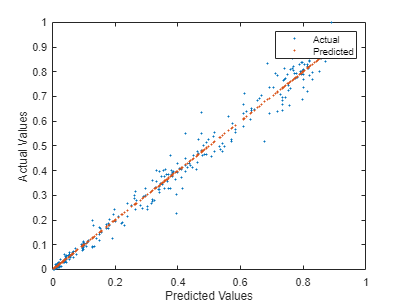

[trainedModel1, validationRMSE1, RMSE1] = RFtrainRegression(datos, 10, 100);

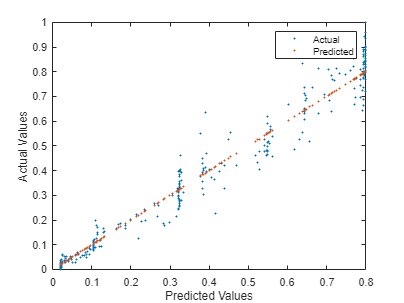

%validationRMSE1
[trainedModel2, validationRMSE2, RMSE2] = RFtrainRegression(datos, 50, 75);

%validationRMSE2

Resultados

modelosRF = ["10 predictores y 100 árboles"; "50 predictores y 75 árboles"];

mse_RF = [RMSE1, RMSE2];

resultadosRF = table(modelosRF, mse_RF');
resultadosRF.Properties.VariableNames = {'Modelos Random Forest', 'MSE'};

disp(resultadosRF);

        Modelos Random Forest           MSE   
    ______________________________    ________

    "10 predictores y 100 árboles"    0.038219
    "50 predictores y 75 árboles"     0.055968



## KNN entrenamiento

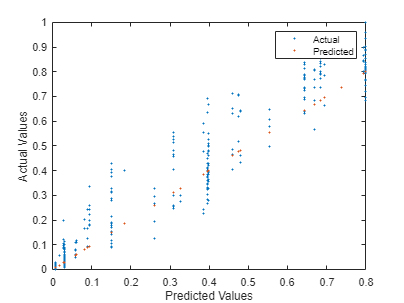

[trainedModel3, RMSE3] = KNNtrainRegression(datos, 'Euclidean', 50);

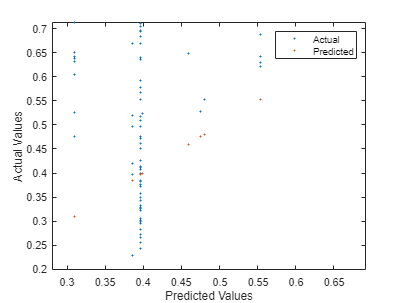

% RMSE3
[trainedModel4, RMSE4] = KNNtrainRegression(datos, 'Euclidean', 100);

% RMSE4

Resultados

modelosKNN = ["50 vecinos"; "100 vecinos"];

mse_KNN = [RMSE3, RMSE4];

resultadosKNN = table(modelosKNN, mse_KNN');
resultadosKNN.Properties.VariableNames = {'Modelos KNN', 'MSE'};

disp(resultadosKNN);

     Modelos KNN       MSE   
    _____________    ________

    "50 vecinos"     0.095914
    "100 vecinos"     0.21921

